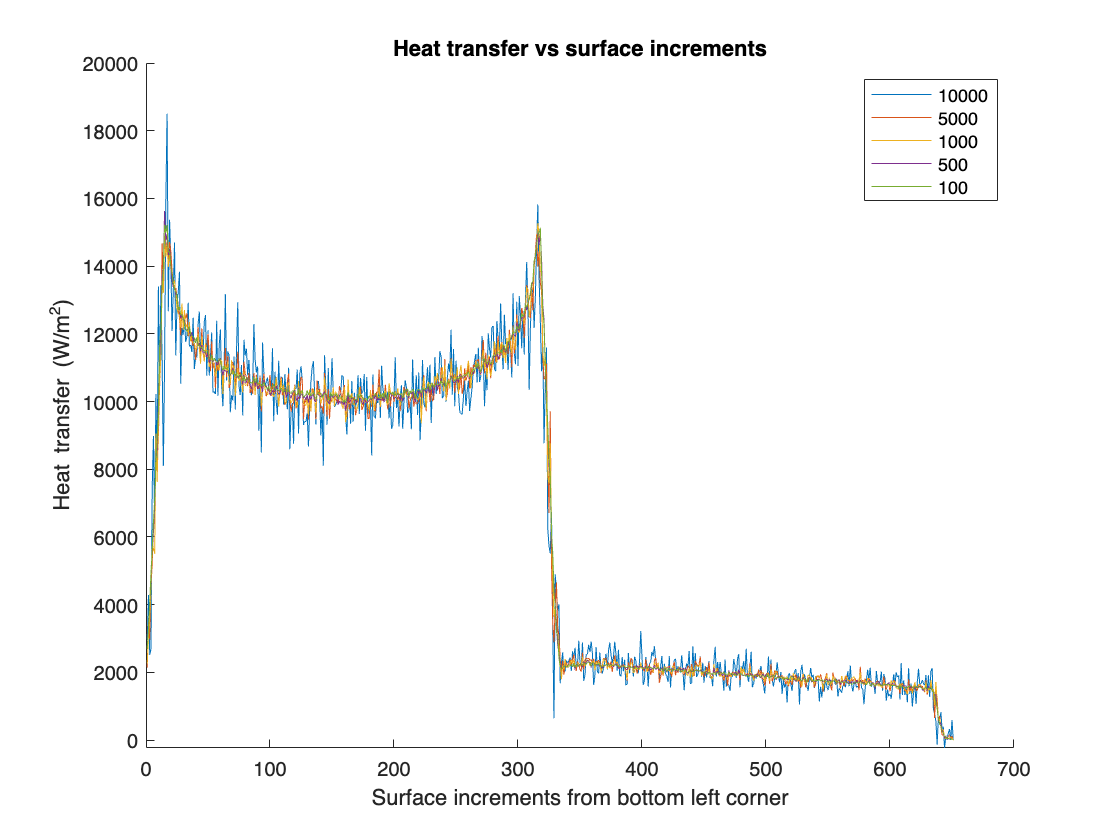

clear

D100=readmatrix('./timestep_average_convergence/surf100.20000.txt');
D100 = sortrows(D100(8:1279,1:10),1);

D500=readmatrix('./timestep_average_convergence/surf500.20000.txt');
D500 = sortrows(D500(8:1279,1:10),1);

D1000=readmatrix('./timestep_average_convergence/surf1000.20000.txt');
D1000 = sortrows(D1000(8:1279,1:10),1);

D5000=readmatrix('./timestep_average_convergence/surf5000.20000.txt');
D5000 = sortrows(D5000(8:1279,1:10),1);

D10000=readmatrix('./timestep_average_convergence/surf10000.20000.txt');
D10000 = sortrows(D10000(8:1279,1:10),1);


figure;
hold on
plot(D100(1:651,1),D100(1:651,10))
plot(D500(1:651,1),D500(1:651,10))
plot(D1000(1:651,1),D1000(1:651,10))
plot(D5000(1:651,1),D5000(1:651,10))
plot(D10000(1:651,1),D10000(1:651,10))
legend('10000','5000','1000','500','100')
xlabel('Surface increments from bottom left corner')
ylabel('Heat transfer (W/m^2)')
title('Heat transfer vs surface increments')

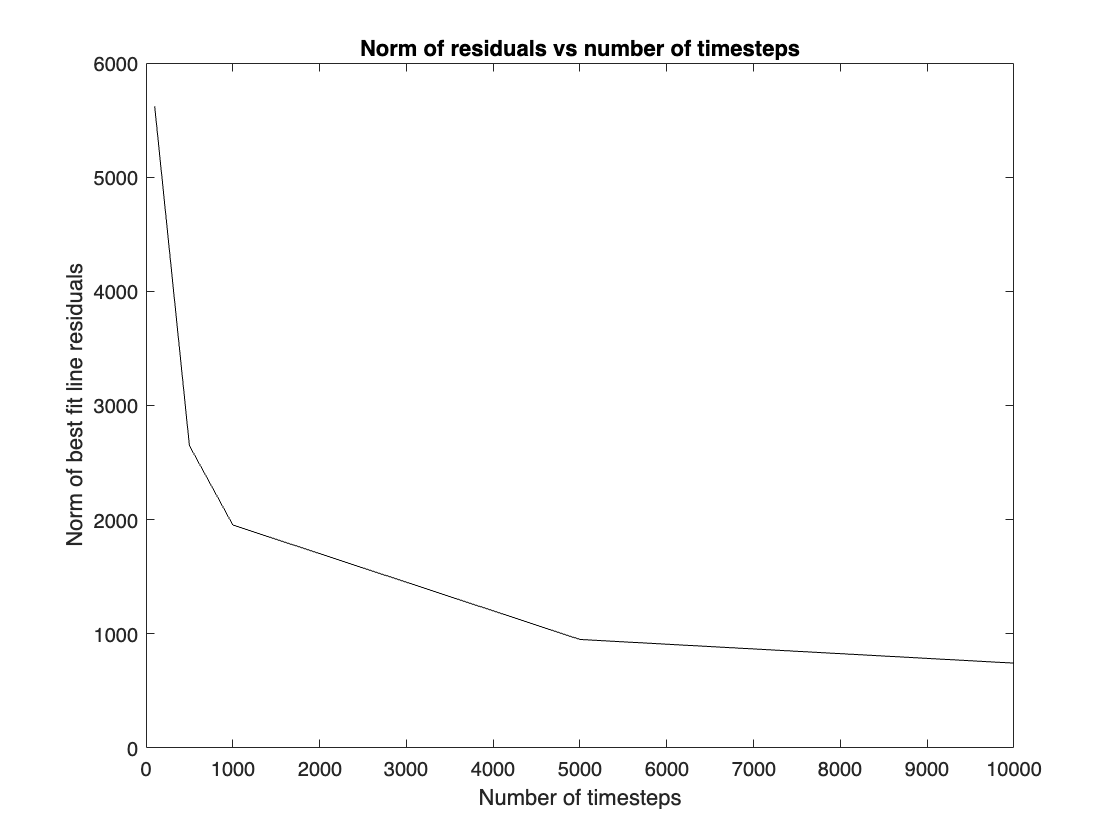



[p100, S100] = polyfit(D100(334:636,1),D100(334:636,10),1);
[p500, S500] = polyfit(D500(334:636,1),D500(334:636,10),1);
[p1000, S1000] = polyfit(D1000(334:636,1),D1000(334:636,10),1);
[p5000, S5000] = polyfit(D5000(334:636,1),D5000(334:636,10),1);
[p10000, S10000] = polyfit(D10000(334:636,1),D10000(334:636,10),1);

nts=[100,500,1000,5000,10000];
gof=[S100.normr,S500.normr,S1000.normr,S5000.normr,S10000.normr];

figure
plot(nts,gof,'k')
xlabel('Number of timesteps')
ylabel('Norm of best fit line residuals')
title('Norm of residuals vs number of timesteps')

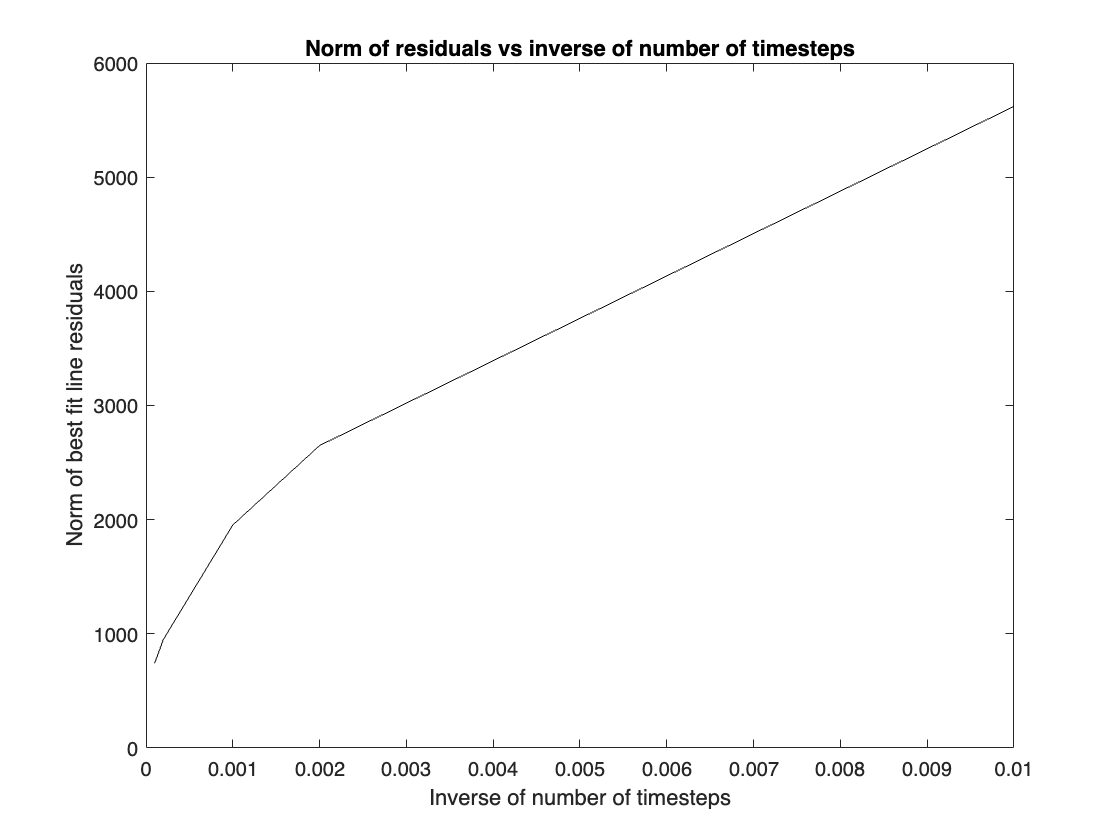


figure
plot(1./nts,gof,'k')
xlabel('Inverse of number of timesteps')
ylabel('Norm of best fit line residuals')
title('Norm of residuals vs inverse of number of timesteps')